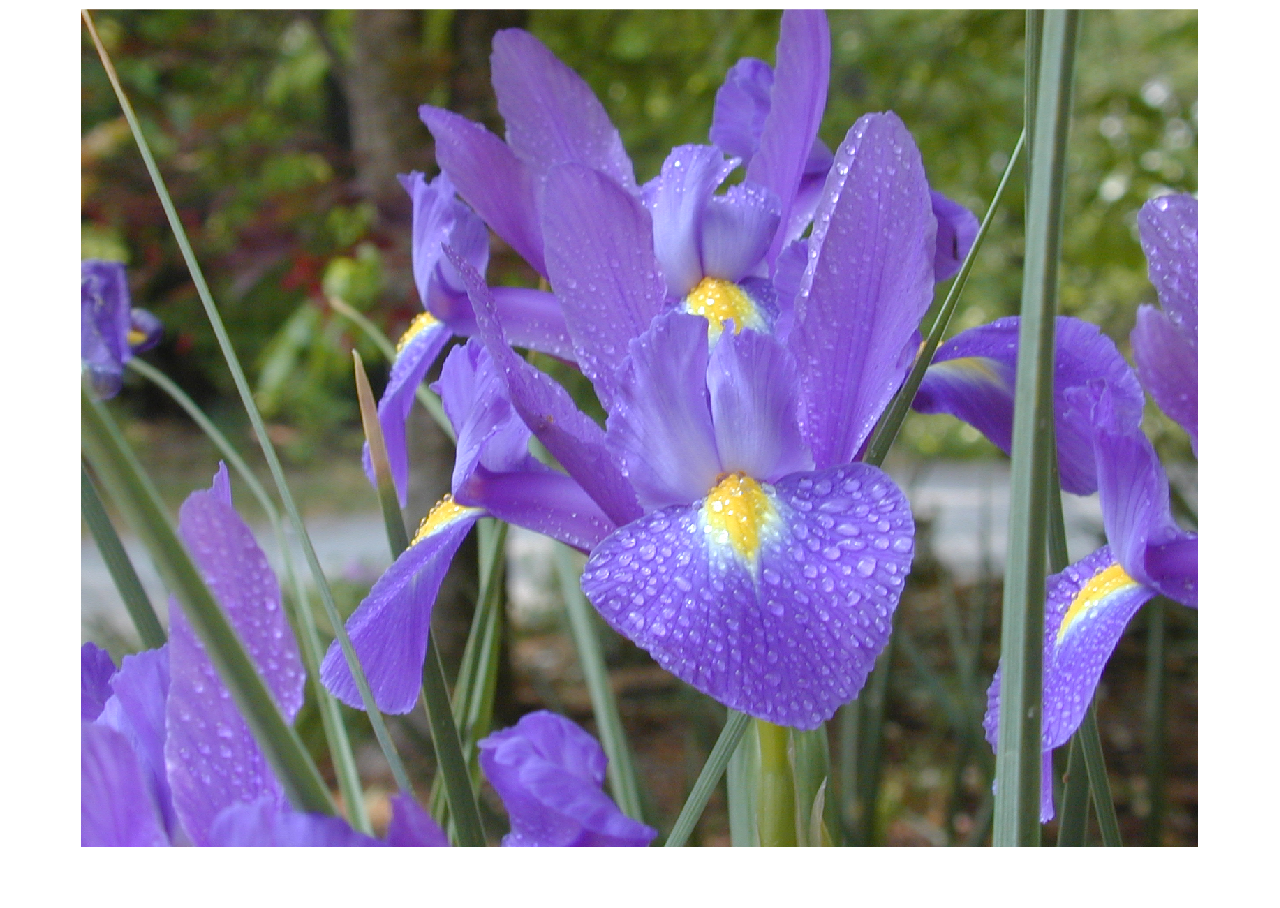

clf; clear;
img = imread("../images/flower.tif");
imshow(img, [])

[M, N, C] = size(img);

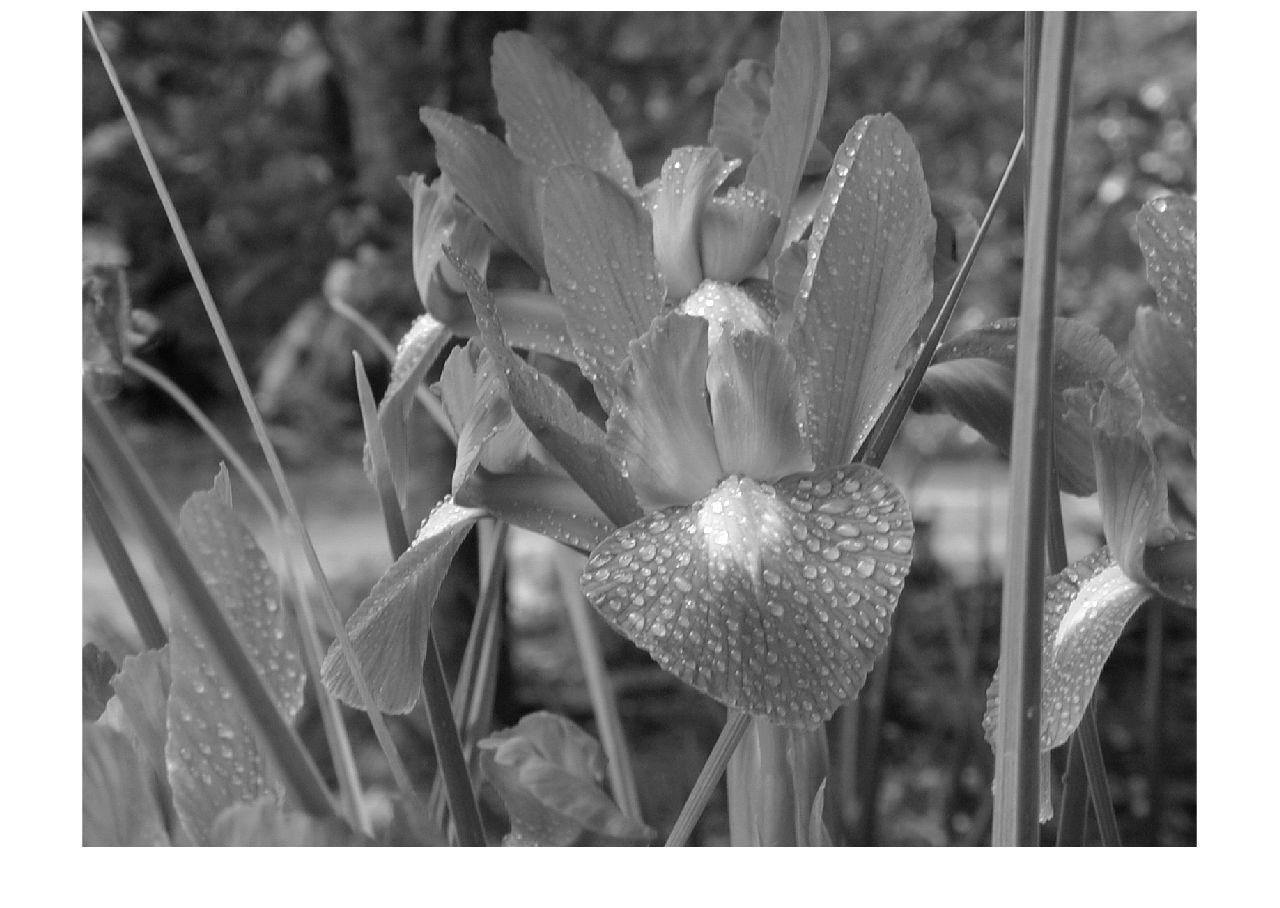

gray_img = rgb2gray(img);
gray_img = double(gray_img) / 255;
imshow(gray_img, [])

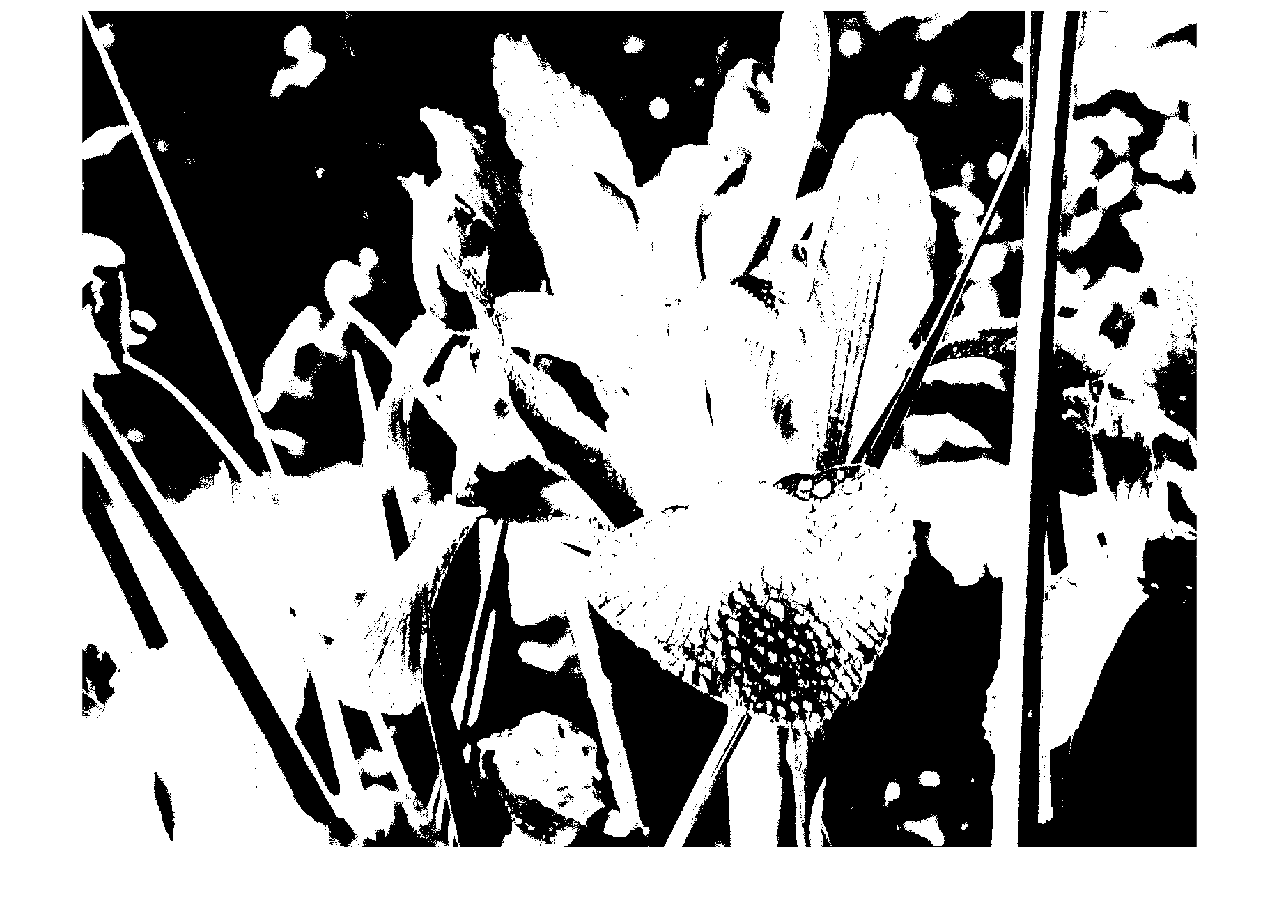

T = 0.001;
delta = 1e10;
eps = 1e-3;
while delta > eps
    A = sum(gray_img(gray_img > T), "all");
    B = sum(gray_img(gray_img <= T), "all");
    m_A = A / sum(gray_img > T, "all");
    m_B = B / sum(gray_img <= T, "all");
    if A == 0
        m_A = 0;
    end
    if B == 0
        m_B = 0;
    end
    T_ = (m_A + m_B) / 2;
    delta = abs(T_ - T);
    T = T_;
end 
gray_img(gray_img > T) = 1;
gray_img(gray_img <= T) = 0;
imshow(gray_img, [])